
$$\frac{\theta_0 \left(s\right)}{\theta_i \left(s\right)}=\frac{\left(\frac{KK_1 K_m K_g }{s\left(s+a\right)\left(s+a_m \right)}\right)}{1+\left(\frac{KK_1 K_m K_g }{s\left(s+a\right)\left(s+a_m \right)}\right)}\times K_{\mathrm{pot}}$$



$$\frac{\theta_0 \left(s\right)}{\theta_i \left(s\right)}=\frac{KK_1 K_m K_g K_{\mathrm{pot}} }{s\left(s+a\right)\left(s+a_m \right)+KK_1 K_m K_g K_{\mathrm{pot}} }$$


num = 48.4475

denum =     1.0000  101.7100  171.0000   48.4475


sys =
 
               48.45
  -------------------------------
  s^3 + 101.7 s^2 + 171 s + 48.45
 
Continuous-time transfer function.



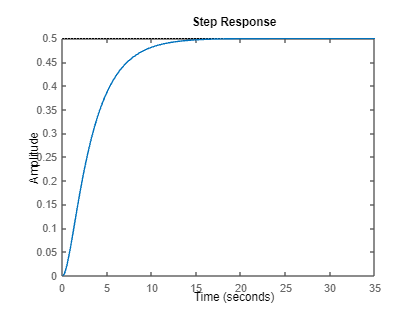

syms s
Kpot = 0.318;
K = 23;% Finding K
K1 = 100;
a = 100;
Km = 2.083;
am = 1.71;
Kg = 0.1;

num = K*Kpot*K1*Km*Kg;
% t = conv(5,conv(1, (1 + am)))
denum = [1 (a+am) (am*a)  K*Kpot*K1*Km*Kg];

sys = tf(num, denum);

step(0.5 * sys)


% maximum overshoot = 5.14%
% Settling Time = 4.87s